 clear
clc
addpath('/Users/mathuser/Documents/PHD/Spring_2022/Inverse Theory/regu')
data = load('gdata.mat');
load('gdata.mat')
m = length(dn);
n = length(rhox);
gamma = 6.67428e-11;

% Compute the height
global h;
h = 25 - sqrt(1/pi);
dx = 1000/n;

% Form the grid points x and y
J = 1:n;
xi = (J-1/2)*dx;

% Form matrix G  
g = @(x,xi) h./((xi-x).^2 + h^2).^(3/2);

G = gamma*dx*g(x,xi);

mfunc = @(alpha,L) (G'*G + alpha^2.*(L'*L))\(G'*dn);

global sigma;
sigma = std(dn);

(a) Interpret the results of your least squares inversion, and analyze the resolution in your model parameter estimates.

% m function
mlsq =(G'*G)\(G'*dn);

(b) Use your regularization parameter selection method as indicated in the above table, which may not be the L-curve. In addition to second-order, invert using zeroth- and first-order Tikhonov regularization.

% Regularized Discrepancy Principle
global delta_reg;
delta_reg = 30;


% The zeroth order Tikhonov regularization
L0 = eye(n);

fun0 = @(alpha) freg(G,alpha,dn,L0);

options = optimset('TolFun',1e-10,'Display','none');
options.TolX = 1e-10;
alphag = 1e-9;
alpha0 = fsolve(fun0,alphag,options)

alpha0 = 1.1061e-15

m0 = mfunc(alpha0,L0);

% The first order Tikhonov regularization
D1 = diag(ones(n-1,1),1);
L1 = -eye(n-1,n) + D1(1:n-1,:);

fun1 = @(alpha) freg(G,alpha,dn,L1);

options = optimset('TolFun',1e-10,'Display','none');
options.TolX = 1e-10;
alpha1 = fsolve(fun1,alphag,options);
m1 = mfunc(alpha1,L1);

% The second order Tikhonov regularization
D2 = -2*diag(ones(n-1,1),1) + diag(ones(n-2,1),2);
L2 = eye(n-2,n) + D2(1:n-2,:);

fun2 = @(alpha) freg(G,alpha,dn,L2);

options = optimset('TolFun',1e-10,'Display','none');
options.TolX = 1e-10;

alpha2 = fsolve(fun2,alphag,options)

alpha2 = 3.2461e-16

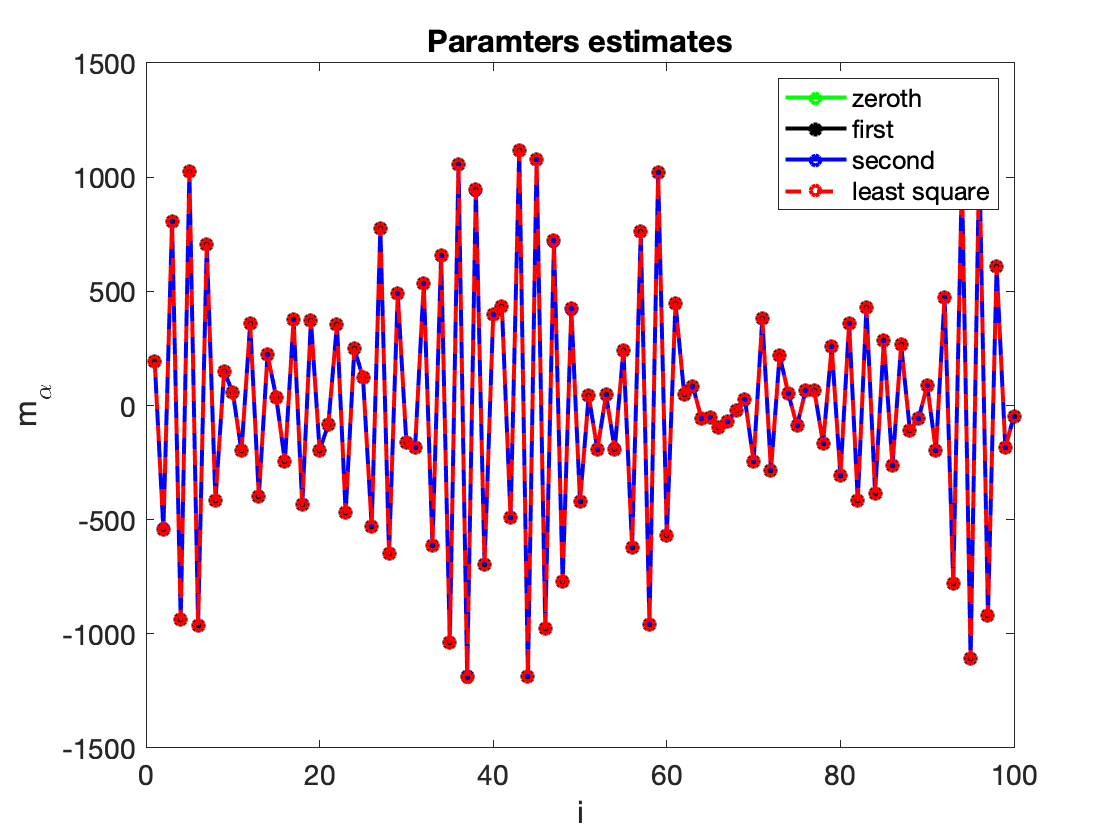

m2 = mfunc(alpha2,L2);
figure(1)
plot(m0,'-go','LineWidth',2,"MarkerSize",5)
hold on
plot(m1,'-k*','LineWidth',2,"MarkerSize",5)
plot(m2,'-bo','LineWidth',2,"MarkerSize",5)
plot(mlsq,'--ro','LineWidth',2,"MarkerSize",5)
h_gc = gca;
h_gc.FontSize = 14;
xlabel('i')
ylabel('m_{\alpha}'); 
legend('zeroth', 'first','second','least square')
title('Paramters estimates')
hold off

c) Show results when inverting by just adding bounds to the least squares problem (Section 4.9 and textbook function bvls).

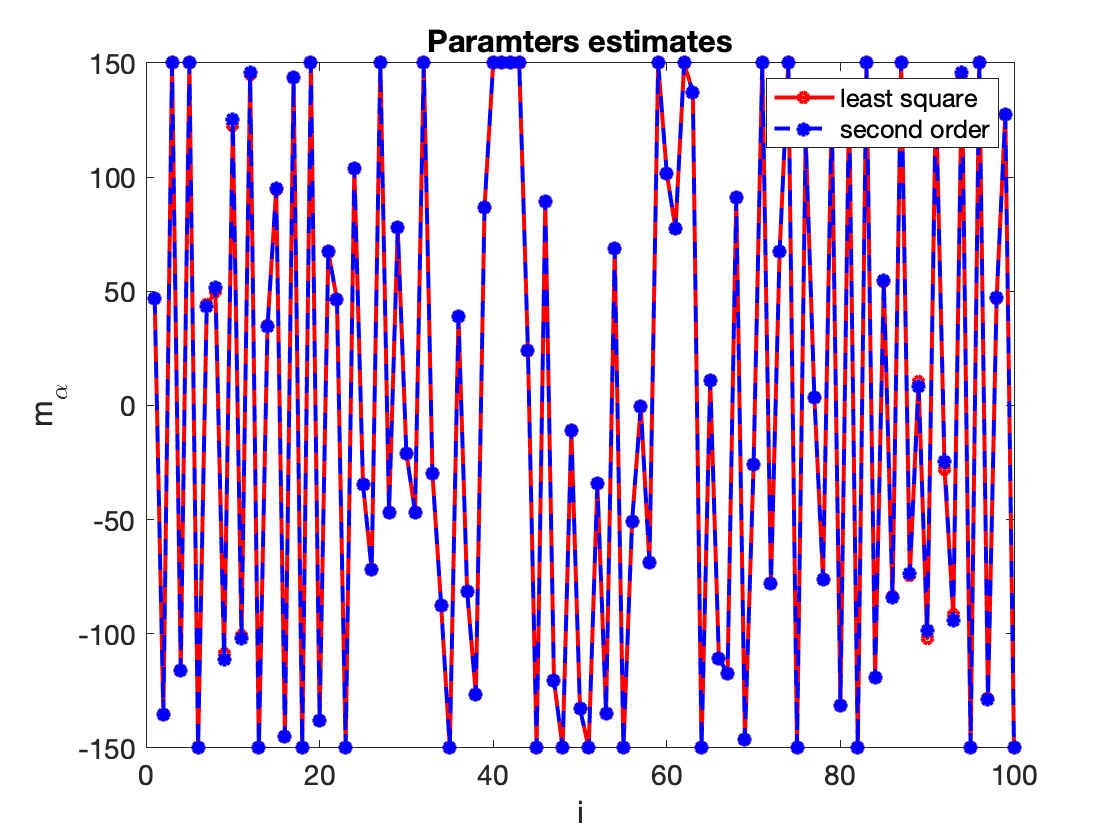

l = -150*ones(n,1);
u = 150*ones(n,1);

B1 = find(xi < 91); b1 = B1(end);

B2 = find(xi > 899); b2 = B2(1);
c = zeros(n,1);

c(b1:b2) = 0.0001*ones(b2-b1+1,1);

% adding bounds to the least squares problem

[mest1, m_max1] = blf2(G, dn, c, delta_reg, l, u,0);

%mest1

A = [G; alpha2*L2];
dpad = [dn; zeros(n-2,1)];

[mest, m_max] = blf2(A, dpad, c, delta_reg, l, u,alpha2);

figure(2)
plot(mest1,'-ro','LineWidth',2,"MarkerSize",5)
hold on
plot(mest,'--b*','LineWidth',2,"MarkerSize",5)

h_gc = gca;
h_gc.FontSize = 14;
xlabel('i')
ylabel('m_{\alpha}'); 
legend('least square', 'second order')

title('Paramters estimates')
hold off

function res = freg(G,alpha,d,L)
    
    global delta_reg; global sigma;
    
    m_a = (G'*G + alpha^2.*(L'*L))\(G'*d);
    
    res = norm(G*m_a-d)^2/sigma^2 + alpha^2*norm(L*m_a)^2 - delta_reg;
    
end